ads = audioDatastore("C:\Users\ROG\Downloads\audios\proyecto\aumentos2","IncludeSubfolders",true ,"FileExtensions",".wav","LabelSource","foldernames");

The [`splitEachLabel`](docid:audio_ref#mw_8757c90d-c18a-4d74-88c6-45c3903e8f3e) function of `audioDatastore` splits the datastore into two or more datastores. The resulting datastores have the specified proportion of the audio files from each label. In this example, the datastore is split into two parts. 80% of the data for each label is used for training, and the remaining 20% is used for testing. The [`countEachLabel`](docid:audio_ref#mw_27293e0c-5066-45c4-b34d-e2814c56921f) function of `audioDatastore` is used to count the number of audio files per label. In this example, the label identifies the speaker.

[adsTrain,adsTest] = splitEachLabel(ads,0.8);

Display the datastore and the number of speakers in the train datastore.

adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              ' ...\Downloads\audios\proyecto\aumentos2\adrian\augmented_10_adrian1.wav';
                              ' ...\Downloads\audios\proyecto\aumentos2\adrian\augmented_10_adrian10.wav';
                              ' ...\Downloads\audios\proyecto\aumentos2\adrian\augmented_10_adrian2.wav'
                               ... and 1373 more
                              }
                     Folders: {
                              'C:\Users\ROG\Downloads\audios\proyecto\aumentos2'
                              }
                      Labels: [adrian; adrian; adrian ... and 1373 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
           OutputEnvironment: 'cpu'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
         DefaultO

trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 17×2 table
      Label      Count
    _________    _____

    adrian        80  
    alfredo       80  
    andre         80  
    aris          80  
    bruno         80  
    dan           80  
    fredy         80  
    it            80  
    ivan          80  
    juanpaulo     80  
    majo          80  
    mar           80  
    olguin        80  
    oscar         88  
    pao           80  
    yestli        80  


Display the datastore and the number of speakers in the test datastore.

adsTest

adsTest =   audioDatastore with properties:

                       Files: {
                              ' ...\Downloads\audios\proyecto\aumentos2\adrian\augmented_8_adrian1.wav';
                              ' ...\Downloads\audios\proyecto\aumentos2\adrian\augmented_8_adrian10.wav';
                              ' ...\Downloads\audios\proyecto\aumentos2\adrian\augmented_8_adrian2.wav'
                               ... and 341 more
                              }
                     Folders: {
                              'C:\Users\ROG\Downloads\audios\proyecto\aumentos2'
                              }
                      Labels: [adrian; adrian; adrian ... and 341 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
           OutputEnvironment: 'cpu'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]
         DefaultOutputF

testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 17×2 table
      Label      Count
    _________    _____

    adrian        20  
    alfredo       20  
    andre         20  
    aris          20  
    bruno         20  
    dan           20  
    fredy         20  
    it            20  
    ivan          20  
    juanpaulo     20  
    majo          20  
    mar           20  
    olguin        20  
    oscar         22  
    pao           20  
    yestli        20  


To preview the content of your datastore, read a sample file and play it using your default audio device.

[sampleTrain,dsInfo] = read(adsTrain);
sound(sampleTrain,dsInfo.SampleRate)

Reading from the train datastore pushes the read pointer so that you can iterate through the database. Reset the train datastore to return the read pointer to the start for the following feature extraction.

reset(adsTrain)

## Feature Extraction

Extract pitch and MFCC features from each frame that corresponds to voiced speech in the training datastore. Audio Toolbox™ provides `audioFeatureExtractor` so that you can quickly and efficiently extract multiple features. Configure an [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) to extract pitch, short-time energy, zcr, and MFCC.

fs = dsInfo.SampleRate;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"),OverlapLength=overlapLength, ...
    zerocrossrate=true,shortTimeEnergy=true,pitch=true,mfcc=true);

When you call the extract function of `audioFeatureExtractor`, all features are concatenated and returned in a matrix. You can use the info function to determine which columns of the matrix correspond to which features.

featureMap = info(afe)

featureMap = struct with fields:
               mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]
              pitch: 14
      zerocrossrate: 15
    shortTimeEnergy: 16


Extract features from the data set.

features = [];
labels = [];
energyThreshold = 0.015;
zcrThreshold = 0.5;

allFeatures = extract(afe,adsTrain);
allLabels = adsTrain.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    label = repelem(allLabels(ii),size(thisFeature,1));
    
    features = [features;thisFeature];
    labels = [labels,label];
end

Pitch and MFCC are not on the same scale. This will bias the classifier. Normalize the features by subtracting the mean and dividing the standard deviation.

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;

## Train Classifier

Now that you have collected features for all 10 speakers, you can train a classifier based on them. In this example, you use a K-nearest neighbor (KNN) classifier. KNN is a classification technique naturally suited for multiclass classification. The hyperparameters for the nearest neighbor classifier include the number of nearest neighbors, the distance metric used to compute distance to the neighbors, and the weight of the distance metric. The hyperparameters are selected to optimize validation accuracy and performance on the test set. In this example, the number of neighbors is set to 5 and the metric for distance chosen is squared-inverse weighted Euclidean distance. For more information about the classifier, refer to [`fitcknn`](docid:stats_ug#bt6cr9l).

Train the classifier and print the cross-validation accuracy. [`crossval`](docid:stats_ug#mw_f146c8ce-56ce-4f92-82c6-b22ad9bb0376) and [`kfoldloss`](docid:stats_ug#bsu1r2a-1) are used to compute the cross-validation accuracy for the KNN classifier.

Specify all the classifier options and train the classifier.

trainedClassifier = fitcknn(features,labels, ...
    Distance="euclidean", ...
    NumNeighbors=20, ...
    DistanceWeight="squaredinverse", ...
    Standardize=false, ...
    ClassNames=unique(labels));

Perform cross-validation.

k = 20;
group = labels;
c = cvpartition(group,KFold=k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,CVPartition=c);

Compute the validation accuracy.

validationAccuracy = 1 - kfoldLoss(partitionedModel,LossFun="ClassifError");
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 83.65%


Visualize the confusion chart.

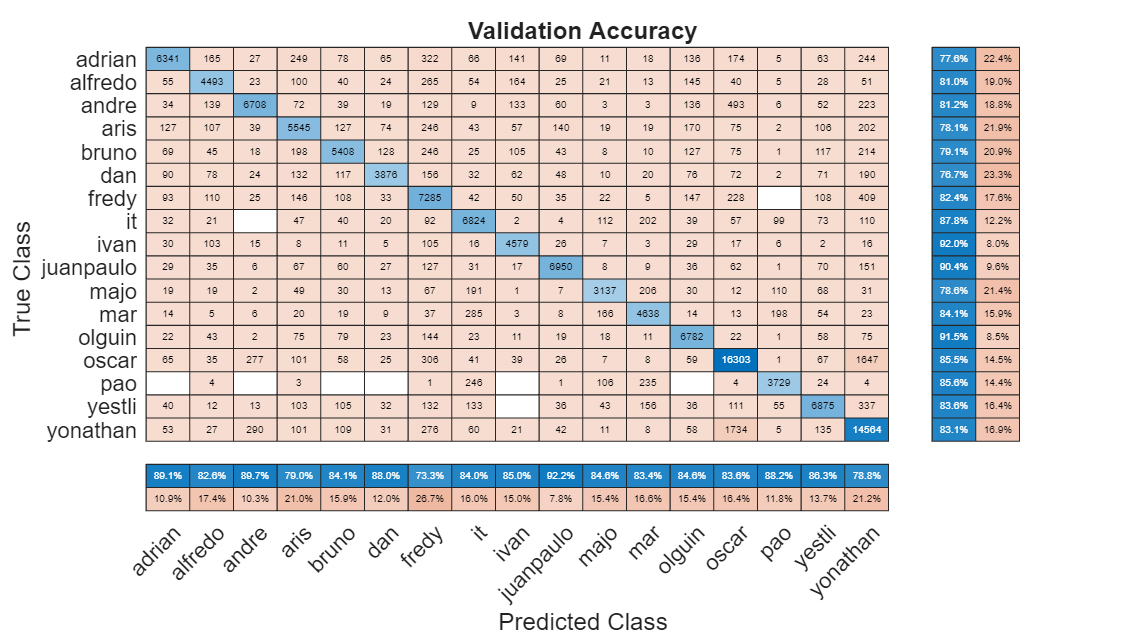

validationPredictions = kfoldPredict(partitionedModel);
figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels,validationPredictions,title="Validation Accuracy", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

You can also use the [`Classification Learner`](docid:stats_ug#buggk6h) app to try out and compare various classifiers with your table of features.

## Test Classifier

In this section, you test the trained KNN classifier with speech signals from each of the 10 speakers to see how well it behaves with signals that were not used to train it. 

Read files, extract features from the test set, and normalize them.

features = [];
labels = [];
numVectorsPerFile = [];

allFeatures = extract(afe,adsTest);
allLabels = adsTest.Labels;

for ii = 1:numel(allFeatures)

    thisFeature = allFeatures{ii};

    isSpeech = thisFeature(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = thisFeature(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    thisFeature(~voicedSpeech,:) = [];
    numVec = size(thisFeature,1);
    thisFeature(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    
    label = repelem(allLabels(ii),numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;thisFeature];
    labels = [labels,label];
end
features = (features-M)./S;

Predict the label (speaker) for each frame by calling `predict` on `trainedClassifier`.

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

Visualize the confusion chart.

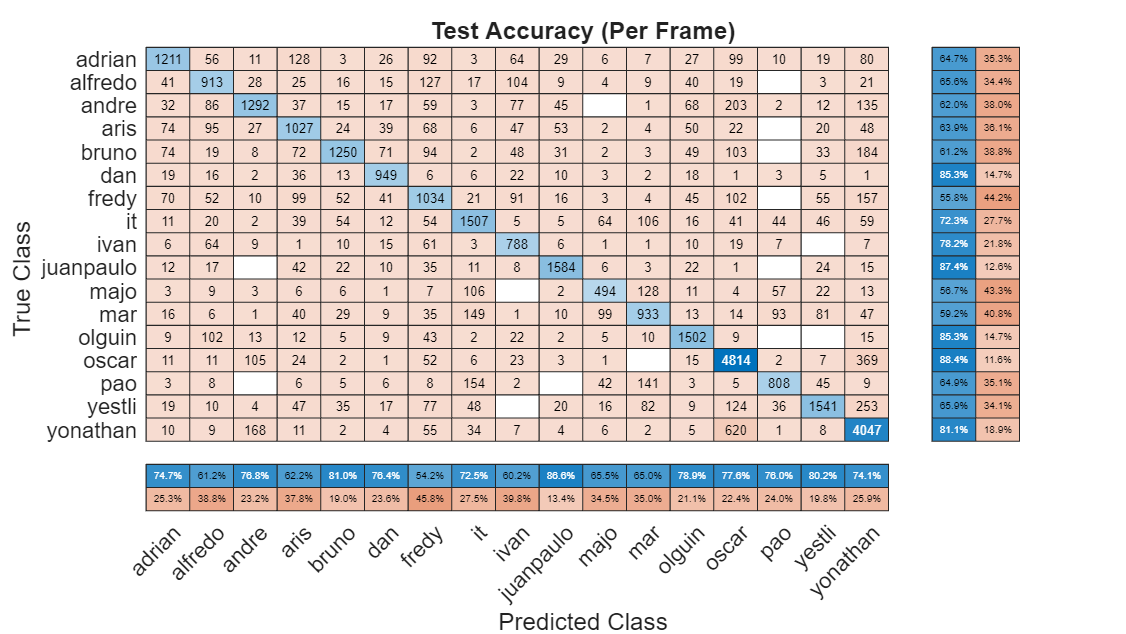

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels(:),prediction,title="Test Accuracy (Per Frame)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

For a given file, predictions are made for every frame. Determine the mode of predictions for each file and then plot the confusion chart.

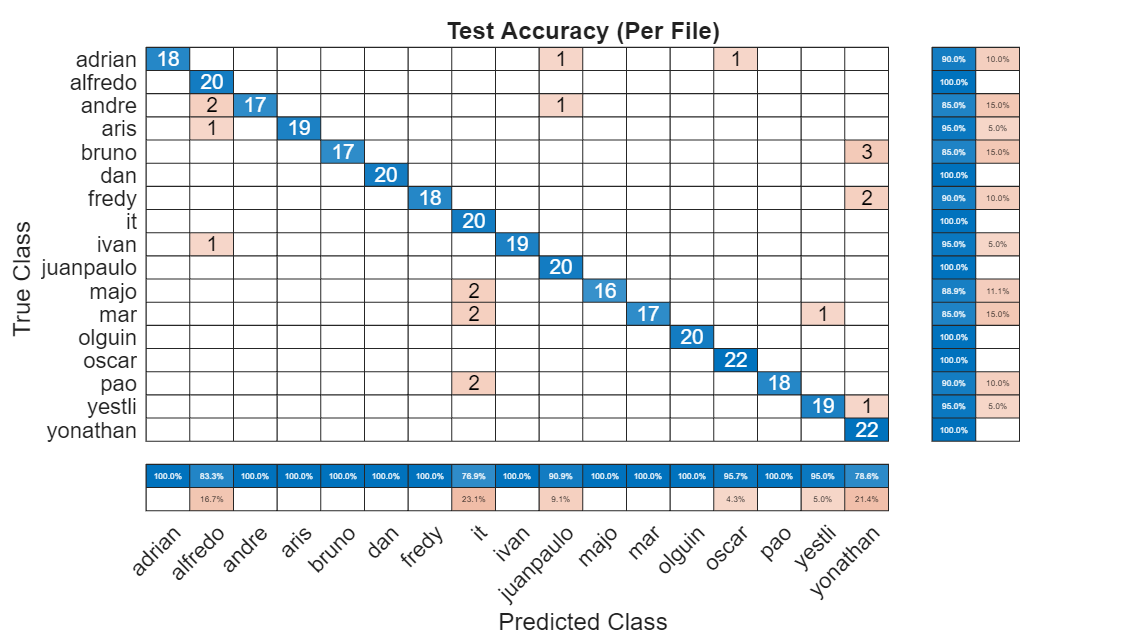

r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(adsTest.Labels,r2,title="Test Accuracy (Per File)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

The predicted speakers match the expected speakers for all files under test.

## Guardado de archivos .mat

% Guardar las variables normalizadas en esa ruta
save("C:\Users\ROG\Downloads\audios\proyecto\mat\archivos1.mat", 'features', 'labels', 'trainedClassifier','M','S');

## References

[1] [Mozilla Common Voice](https://commonvoice.mozilla.org/)

*Copyright 2017-2023 The MathWorks, Inc.*